# getTimetableFromLoggedSignal - sample script

model_name = "testmodel_getTimetableFromLoggedSignal";
load_system(model_name);

Set up Simscape selective data logging. There is no need to do this every time opening the model because the set up is saved in the model. The code below is for demonstration purpose of how to programmatically set it up.

block_path = model_name + "/PS Lookup Table (1D)";

logging_settings = simscape.instrumentation.defaultVariableTable(block_path);
logging_settings("I").Logging = "off";
logging_settings("O").Logging = "on";
logging_settings("O").Name = "Simscape LUT output";
logging_settings("O").Unit = "N*m";
simscape.instrumentation.setVariableTable(block_path, logging_settings)

logging_settings = simscape.instrumentation.getVariableTable(block_path);
disp(logging_settings)

  VariableTable (string ⟼ VariableConfiguration) with 2 variable(s):

                   Name              Unit      Logging
           _____________________    _______    _______

    I ⟼    <missing>                {["" ]}     false 
    O ⟼    "Simscape LUT output"    {[N*m]}     true  



block_path = model_name + "/PS Transfer Function";

logging_settings = simscape.instrumentation.defaultVariableTable(block_path);
logging_settings("U").Logging = "off";
logging_settings("Y0").Logging = "off";
logging_settings("Y").Logging = "on";
logging_settings("Y").Name = "Simscape TF output";
logging_settings("Y").Unit = "N*m";
simscape.instrumentation.setVariableTable(block_path, logging_settings)

logging_settings = simscape.instrumentation.getVariableTable(block_path);
disp(logging_settings)

  VariableTable (string ⟼ VariableConfiguration) with 4 variable(s):

                    Name             Unit      Logging
            ____________________    _______    _______

    R  ⟼    <missing>               {["" ]}     false 
    U  ⟼    <missing>               {["" ]}     false 
    Y  ⟼    "Simscape TF output"    {[N*m]}     true  
    Y0 ⟼    <missing>               {["" ]}     false 



Run simulation

sim_out = sim(model_name);
% result1 = extractTimetable(sim_out.logsout);
tt = SignalUtil1.getTimetableFromLoggedSignal(sim_out.logsout);
disp(tt)

         Time         Simulink TF in     Output 1       Data_3        Data_4       Simscape LUT output    Simscape TF output    Simulink TF out
    ______________    ______________    __________    __________    ___________    ___________________    __________________    _______________

    0 sec                        1               0             0              0                  1                     0                   0   
    2.5298e-05 sec               1      2.5298e-05    2.5298e-05     6.5662e-18                  1            2.5298e-05          2.5298e-05   
    0.00025298 sec               1      0.00025292    0.00025292     6.5594e-18                  1  

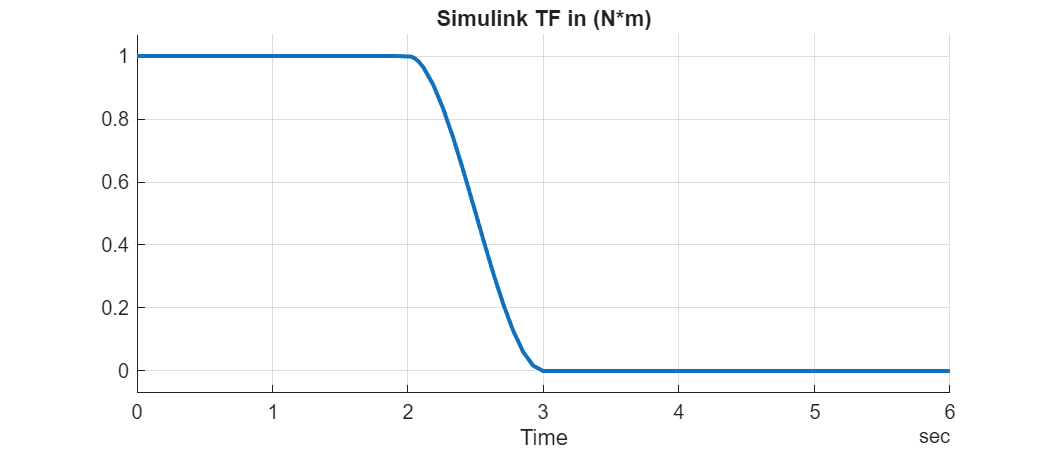

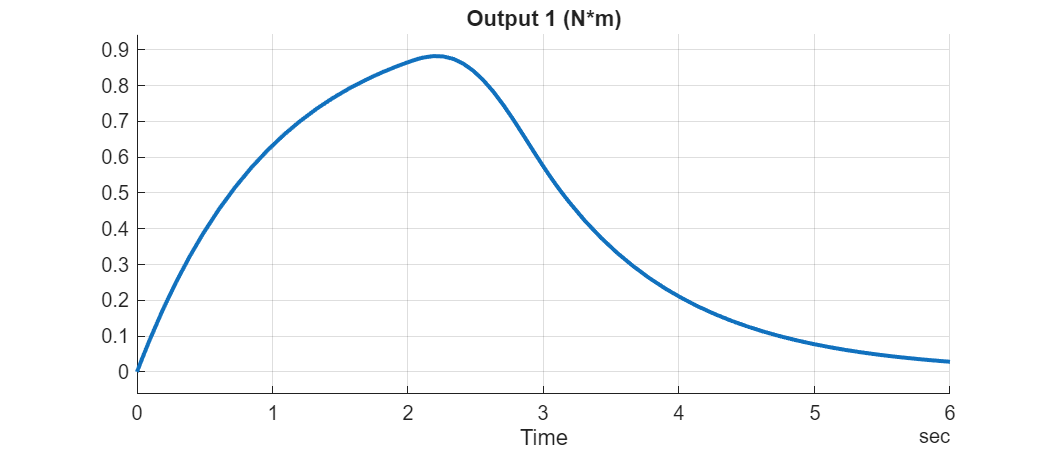

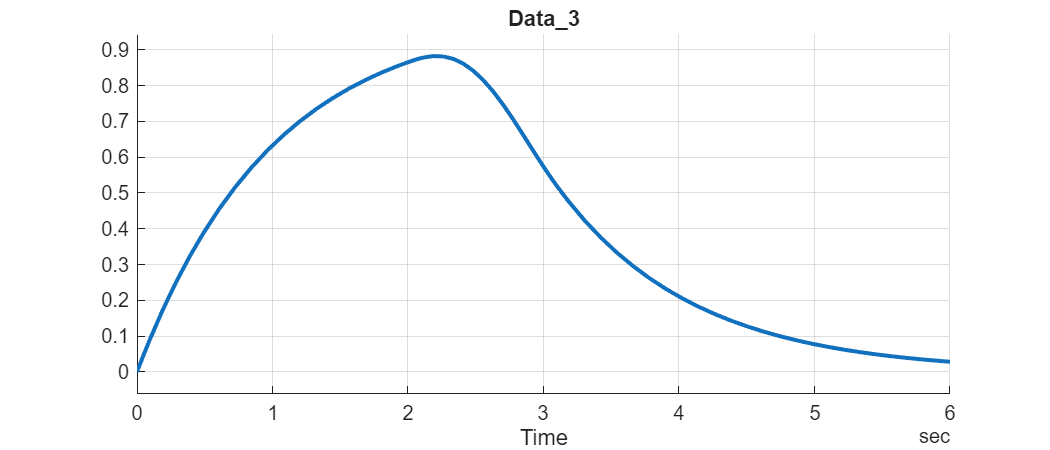

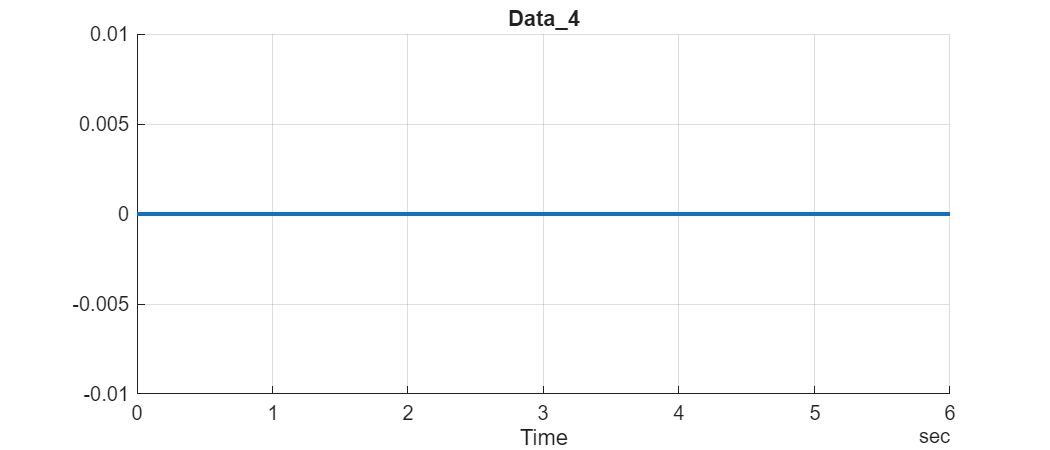

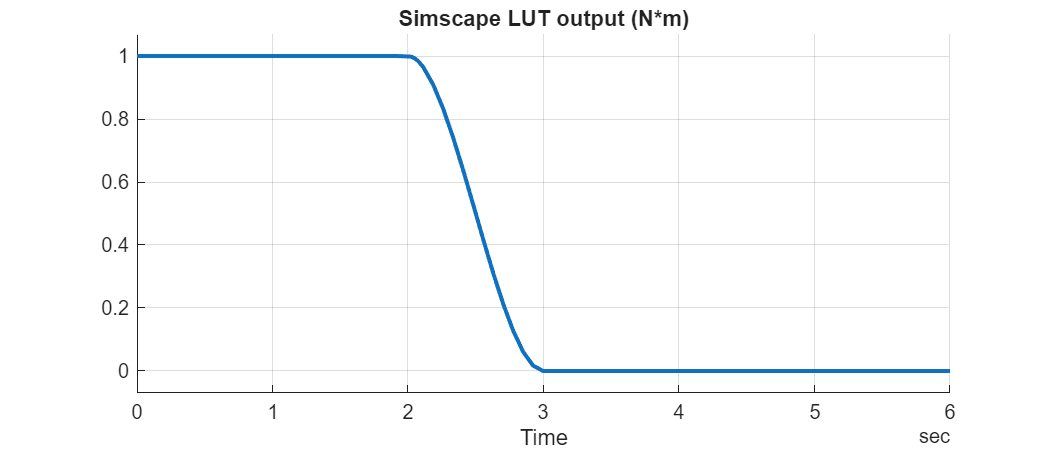

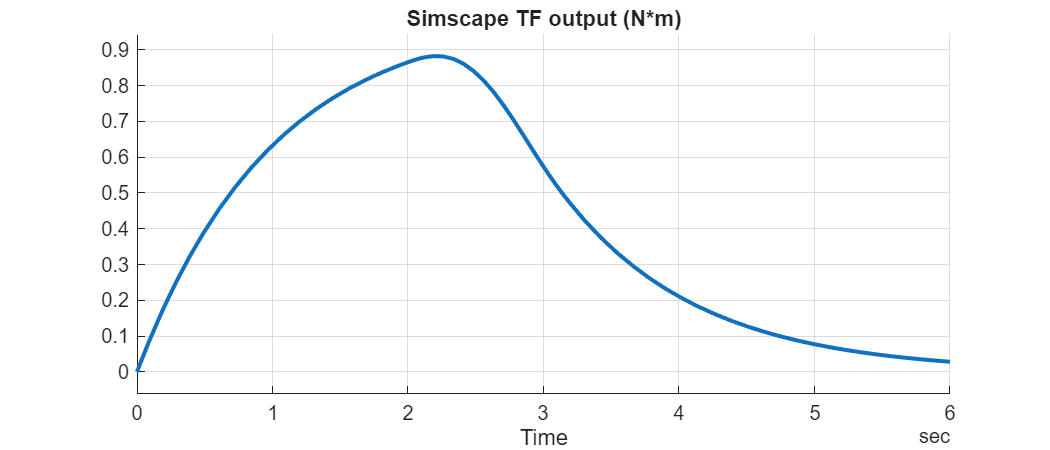

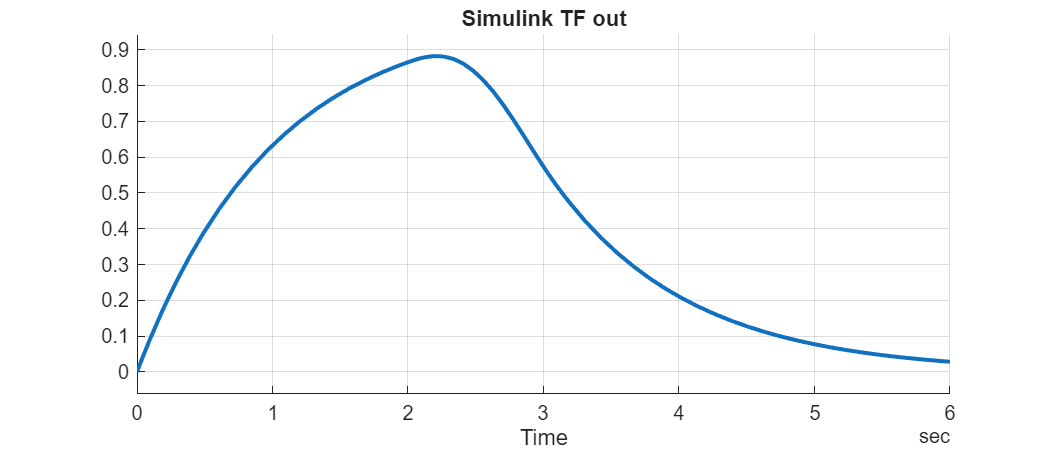

varnames = string(tt.Properties.VariableNames);
for idx = 1 : numel(varnames)
  SignalUtil1.plotTimedData(TimedData=tt, SignalName=varnames(idx));
end  % for

*Copyright 2025 The MathWorks, Inc.*